## Tuberculosis Data - Complete Pairwise interactions

7/23/20

For this run, we are trying something different. I am training on the tuberculosis dataset from Suraj's paper and using the tb "chemogenomics" data, which is really a combination of tb transcriptomics data and ecoli chemogenomic data with mappings to orthologous tb genes.

Doing this allows me to include more drugs in the data because more are included in the chemogenomic data.

**Training Data Article: **[https://mbio.asm.org/content/10/6/e02627-19](https://mbio.asm.org/content/10/6/e02627-19)

**Test Data Article:** nature.com/articles/s41598-019-48410-y

I will do independent validation, and then do cross validation on the data

%Required for obtaining tb chemogenomic data
load('averaged_data_new.mat');
[normData,col,row] = tb_preprocessing(averagedtbdata,mtb_expression_database_col_ids,mtb_expression_database_row_ids);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data


testFile = 'tb_pairwise_complete.xlsx';
trainingData = 'tb_training.xlsx';
valMethod = 'independent';

summaryTable = 1×11 table
     min     median     max     range     mean        std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    _____    ______    _____    _____    _______    _______    ________________    ____________    _______________    _______________    __________

    -1.28    0.2481    1.157    2.437    0.11798    0.54247          128                38               77                true            0.0005  


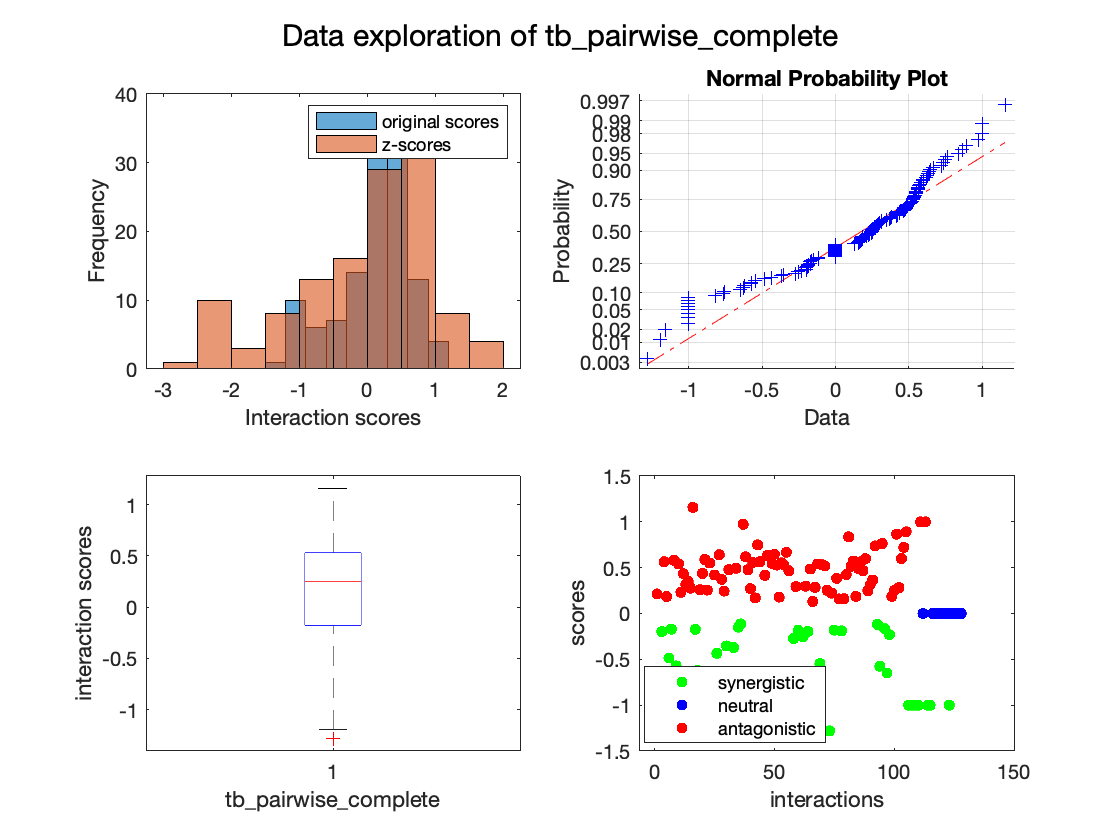

[summary_tb_test,drugList_tb_test] = dataExplore(testFile);

summaryTable = 1×11 table
      min       median       max      range      mean       std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    _______    _________    ______    ______    _______    ______    ________________    ____________    _______________    _______________    __________

    -3.3744    -0.067642    2.0875    5.4619    -0.3748    1.1119          202               100               56                true            0.0005  


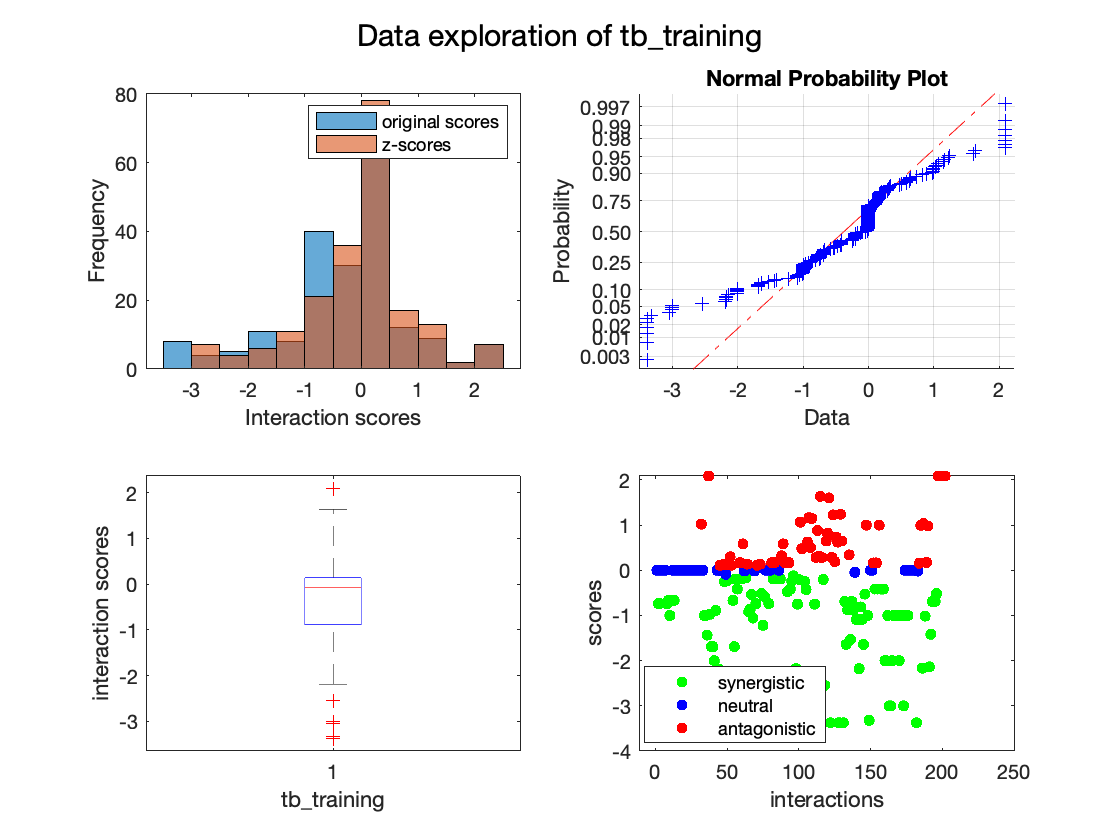

[summary_tb_train,drugList_tb_train] = dataExplore(trainingData);

indigoSummary = indigoRun_tb(testFile,normData,row,col,trainingData,valMethod);

Elapsed time is 6.887753 seconds.


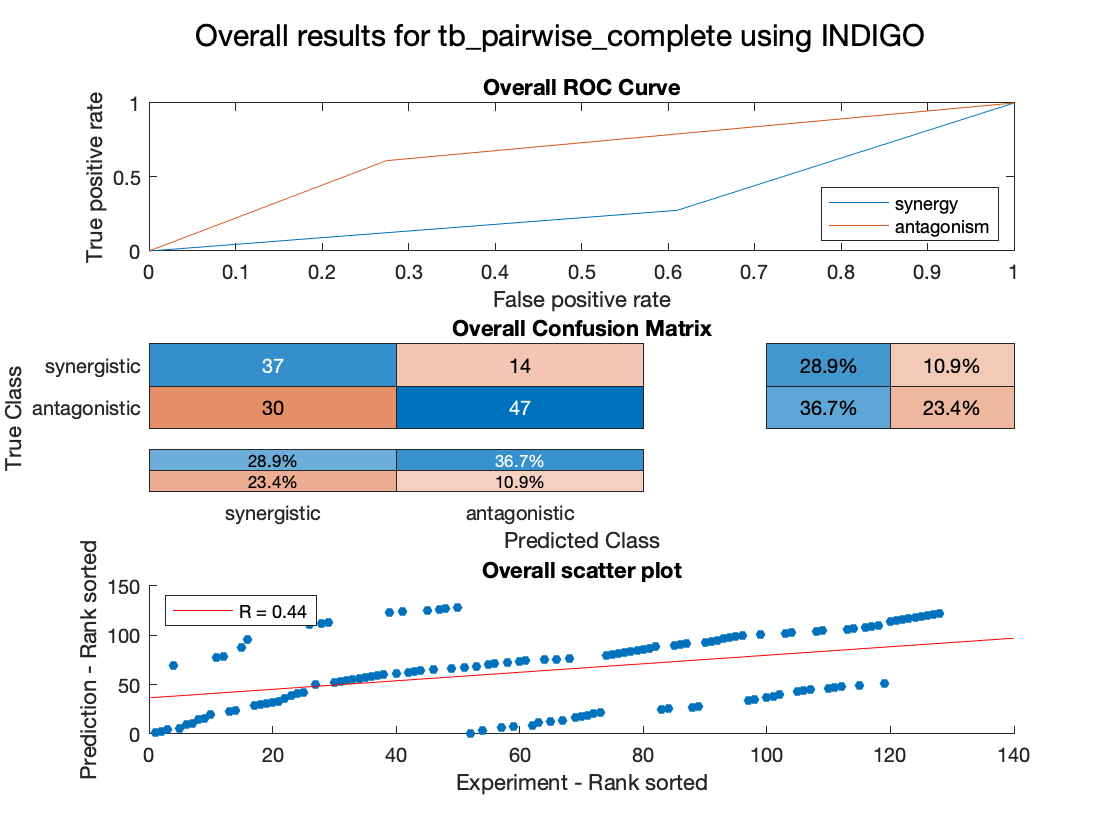

overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                       128
    R (rank)                       0.43824
    P value                     2.2954e-07
    Accuracy                       0.65625
    Absolute error                  0.6875
    Precision (synergy)            0.55224
    Recall (synergy)               0.72549
    Precision (antagonism)         0.77049
    Recall (antagonism)            0.61039
    Guess Accuracy (p value)    1.2422e-69
    AUC - ROC (synergy)            0.33206
    AUC - ROC (antagonism)         0.66794


[~,~,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_pairwise_complete.xlsx';
trainingData = 'tb_training.xlsx';
valMethod = 'independent';
standardize = 'standardized';

indigoSummary = indigoRun_tb(testFile,normData,row,col,trainingData,valMethod,[],standardize);

Elapsed time is 7.244339 seconds.


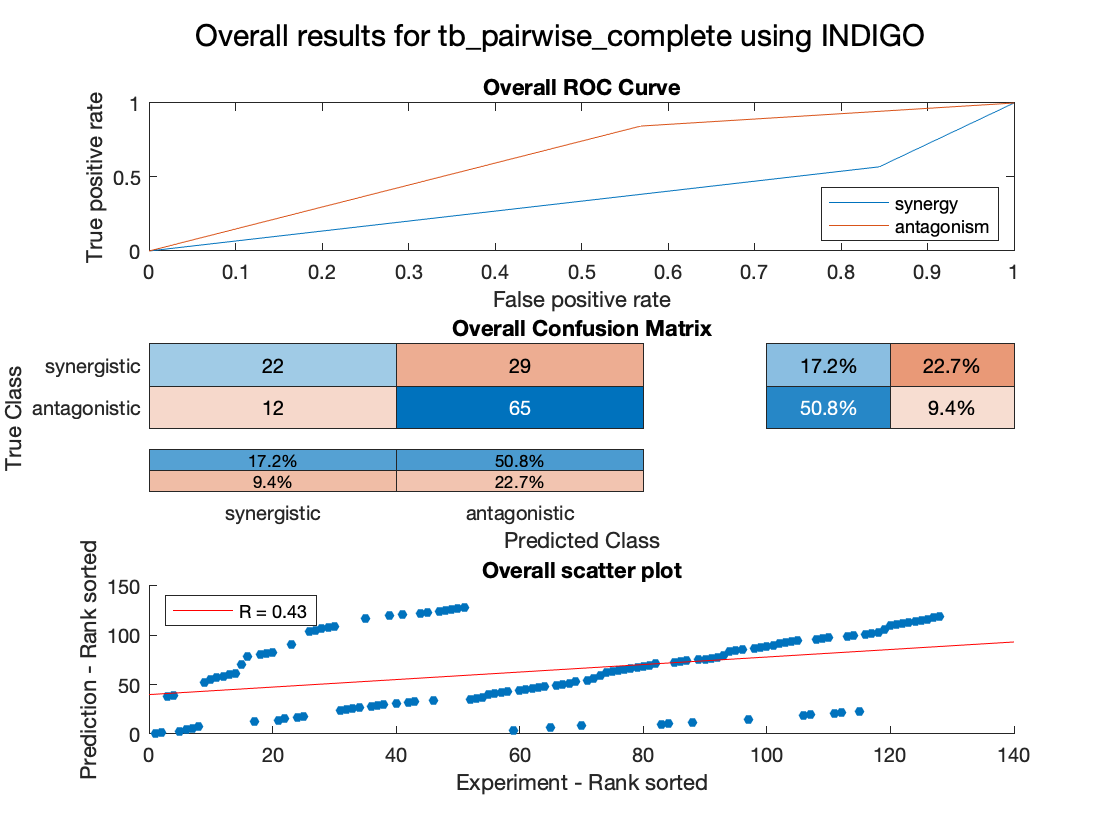

overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                       128
    R (rank)                       0.42967
    P value                     4.1658e-07
    Accuracy                       0.67969
    Absolute error                 0.64062
    Precision (synergy)            0.64706
    Recall (synergy)               0.43137
    Precision (antagonism)         0.69149
    Recall (antagonism)            0.84416
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.36224
    AUC - ROC (antagonism)         0.63776


[~,~,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_pairwise_complete.xlsx';
trainingData = 'tb_training.xlsx';
valMethod = 'cv';
K = 5;

indigoSummary = indigoRun_tb(testFile,normData,row,col,trainingData,valMethod,K);

Run 1
Elapsed time is 12.401910 seconds.
Run 2
Elapsed time is 12.050826 seconds.
Run 3
Elapsed time is 12.554160 seconds.
Run 4
Elapsed time is 11.929336 seconds.
Run 5
Elapsed time is 11.781319 seconds.


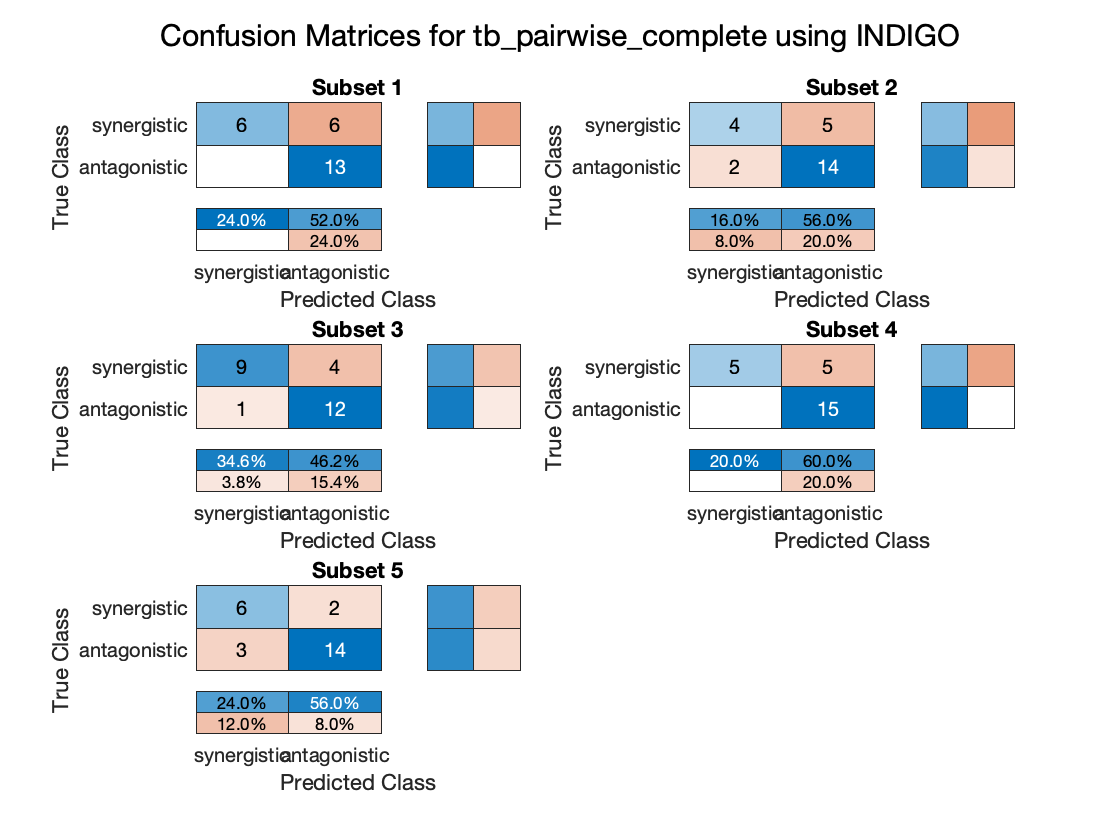

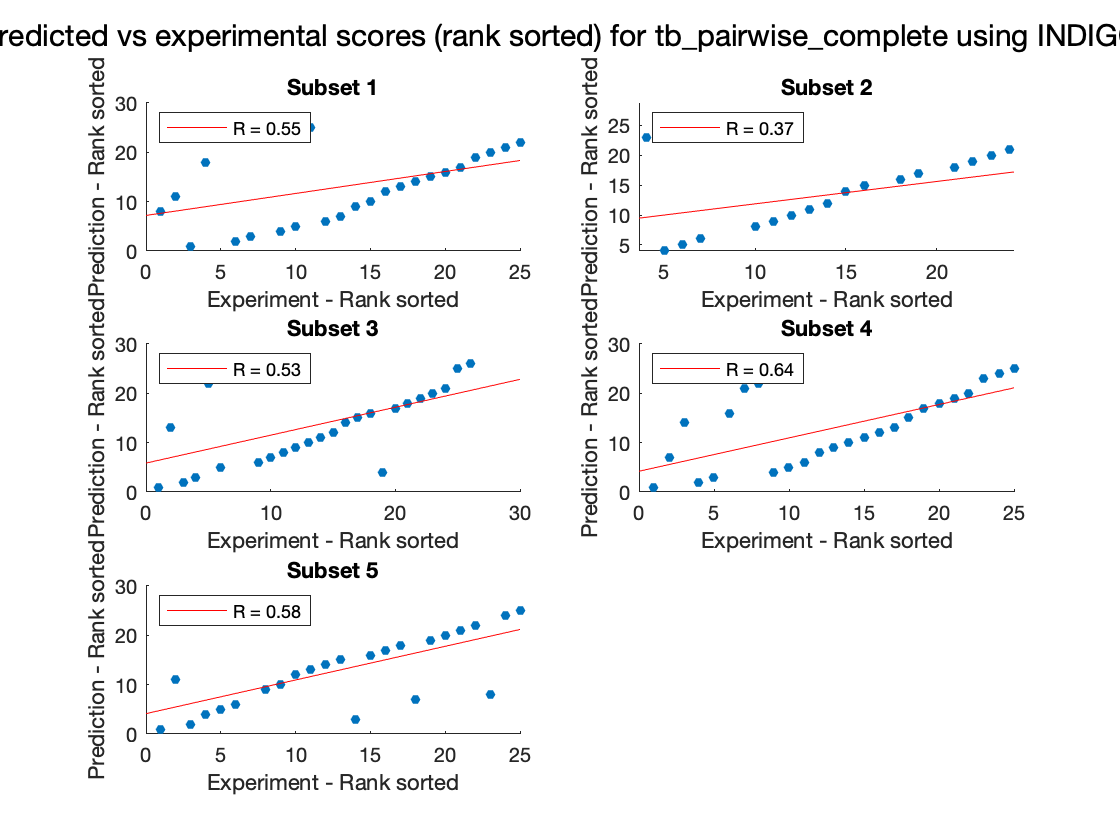

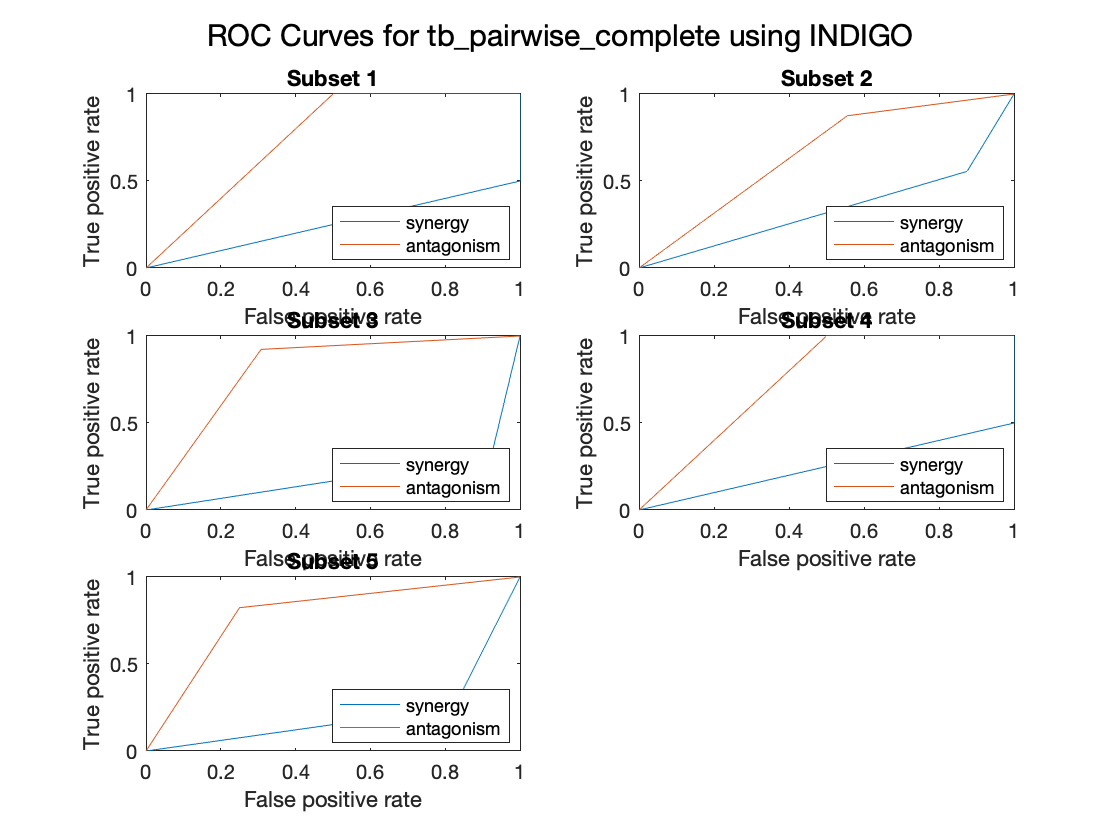

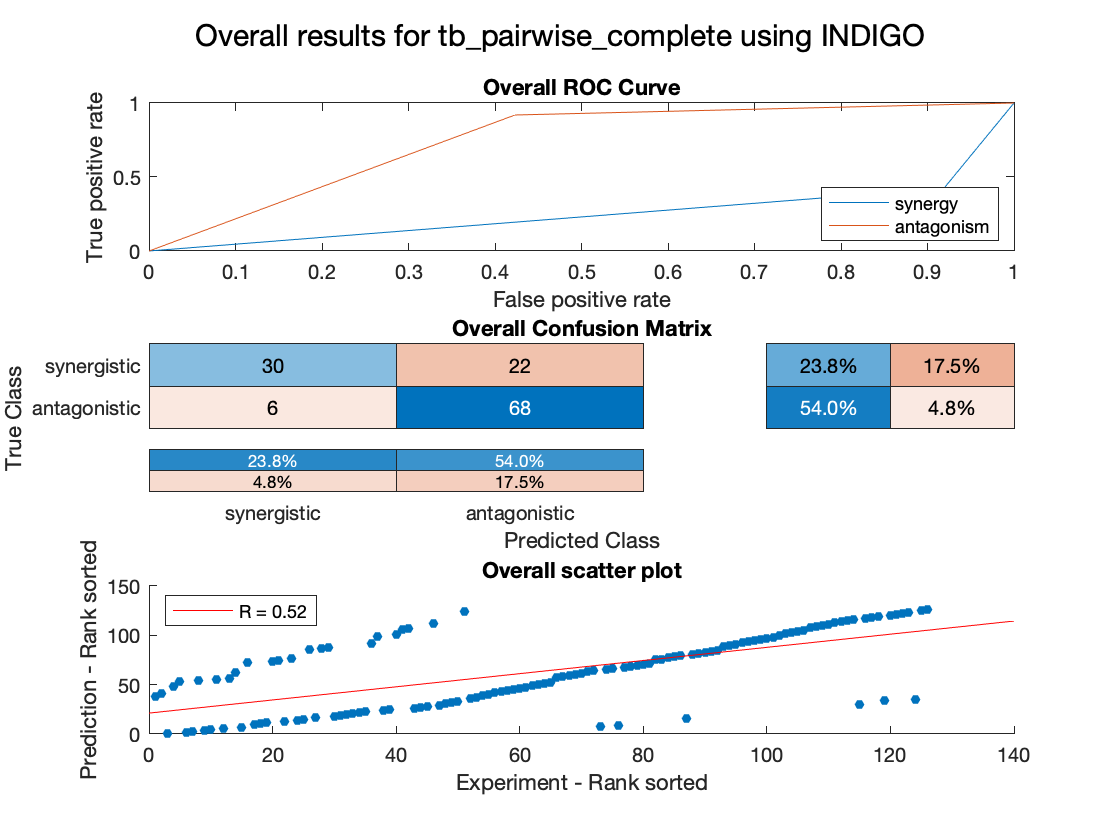

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         25         0.55108 

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                      25.2
    R (rank)                       0.53567
    P value                       0.016741
    Accuracy                       0.77754
    Absolute error                 0.44492
    Precision (synergy)            0.84667
    Recall (synergy)               0.57735
    Precision (antagonism)         0.75921
    Recall (antagonism)            0.92432
    Guess Accuracy (p value)    1.4104e-35
    AUC - ROC (synergy)            0.24916
    AUC - ROC (antagonism)         0.75084


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                       126
    R (rank)                       0.52175
    P value                     3.7329e-10
    Accuracy                       0.77778
    Absolute error                 0.44444
    Precision (synergy)            0.83333
    Recall (synergy)               0.57692
    Precision (antagonism)         0.75556
    Recall (antagonism)            0.91892
    Guess Accuracy (p value)    7.5874e-80
    AUC - ROC (synergy)            0.25208
    AUC - ROC (antagonism)         0.74792


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'tb_pairwise_complete.xlsx';
trainingData = 'tb_training.xlsx';
valMethod = 'cv';
K = 5;
standardize = 'standardized';

indigoSummary = indigoRun_tb(testFile,normData,row,col,trainingData,valMethod,K,standardize);

Run 1
Elapsed time is 11.808626 seconds.
Run 2
Elapsed time is 11.500887 seconds.
Run 3
Elapsed time is 11.527782 seconds.
Run 4
Elapsed time is 11.479514 seconds.
Run 5
Elapsed time is 11.470121 seconds.


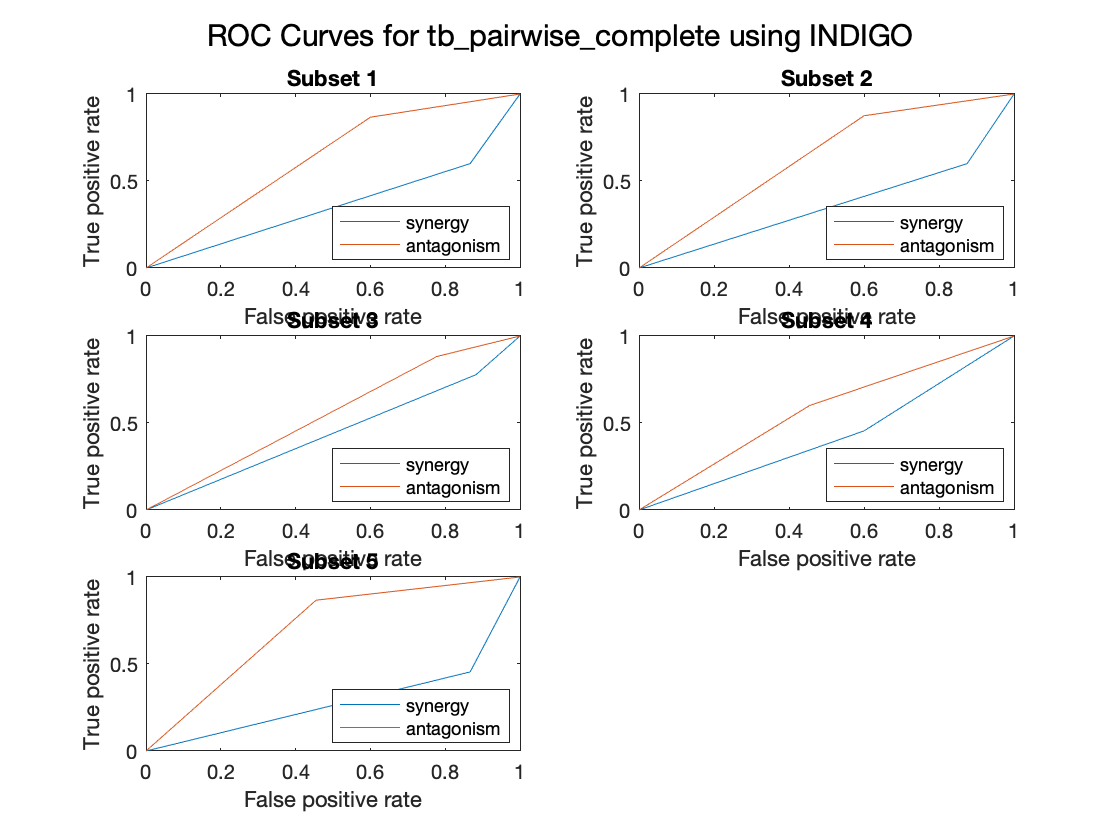

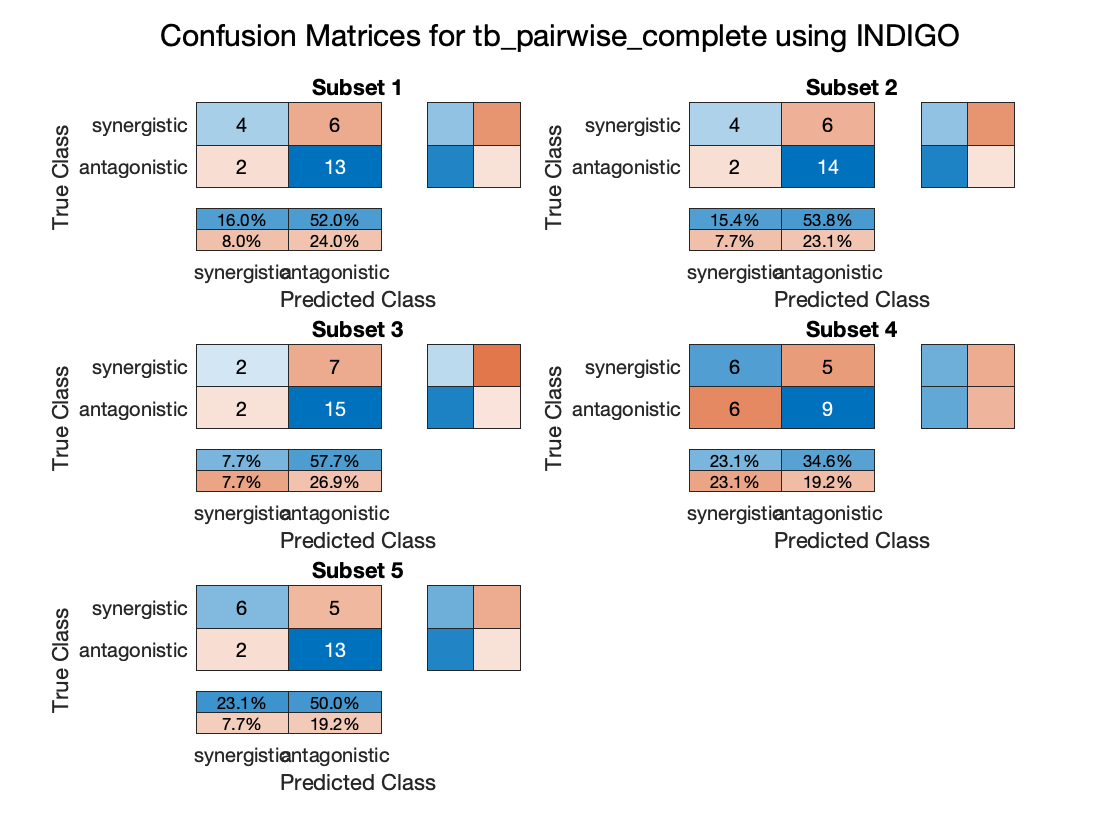

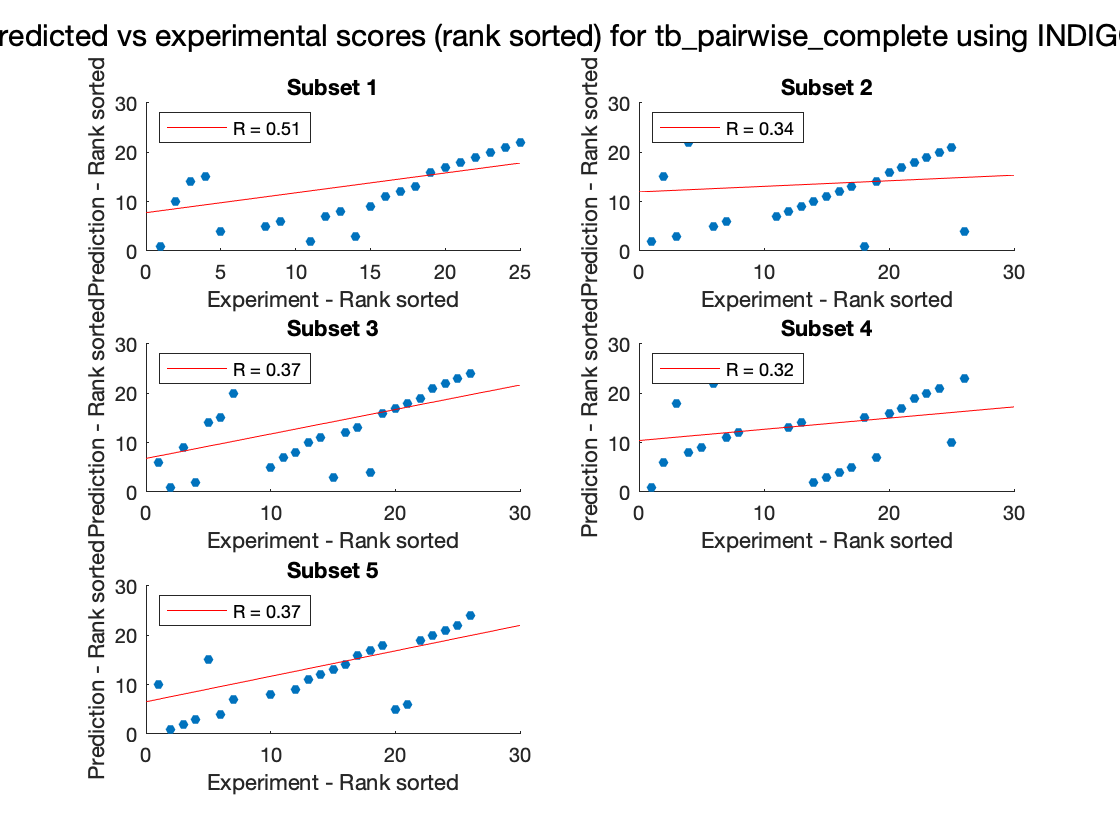

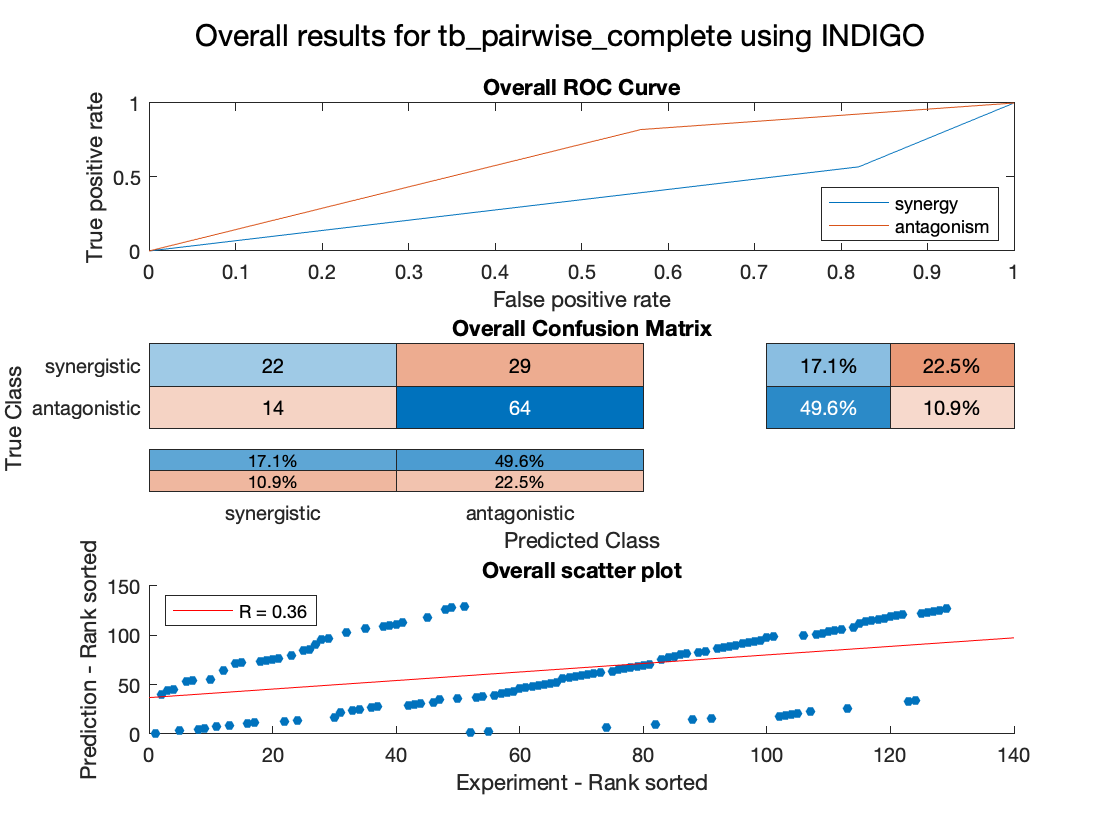

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         25         0.50664   

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                   25.8
    R (rank)                    0.38243
    P value                      0.0661
    Accuracy                    0.66677
    Absolute error              0.66646
    Precision (synergy)         0.61667
    Recall (synergy)            0.42263
    Precision (antagonism)      0.68622
    Recall (antagonism)         0.81814
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.37962
    AUC - ROC (antagonism)      0.62038


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                       129
    R (rank)                       0.36226
    P value                     2.4578e-05
    Accuracy                       0.66667
    Absolute error                 0.66667
    Precision (synergy)            0.61111
    Recall (synergy)               0.43137
    Precision (antagonism)         0.68817
    Recall (antagonism)            0.82051
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.37406
    AUC - ROC (antagonism)         0.62594


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

**Combining all data together into one file**

**tb_full.xlsx**

- tb_training.xlsx

- tb_combos.xlsx - only the values that aren't negative culture data

- tb_pairwise_complete.xlsx

%Required for obtaining tb chemogenomic data
load('averaged_data_new.mat');
[normData,col,row] = tb_preprocessing(averagedtbdata,mtb_expression_database_col_ids,mtb_expression_database_row_ids);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data


testFile = 'tb_all.xlsx';
valMethod = 'cv_onself';
K = 5;

summaryTable = 1×11 table
     min      median     max      range       mean       std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    ______    ______    ______    ______    ________    ______    ________________    ____________    _______________    _______________    __________

    -5.778      0       2.0875    7.8655    -0.22704    1.1063          366               163               151               true            0.0005  


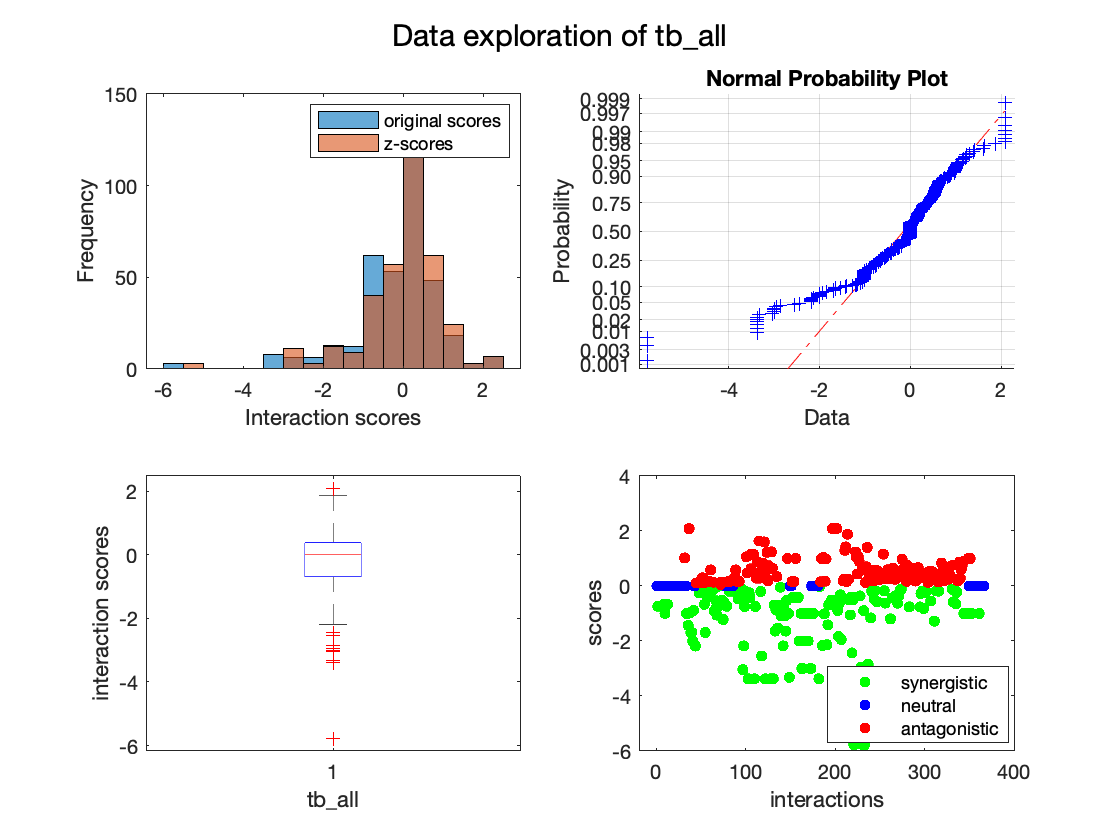

[summary_tb_full,drugList_tb_full] = dataExplore(testFile);

indigoSummary = indigoRun_tb(testFile,normData,row,col,[],valMethod,K);

Run 1
Elapsed time is 13.629575 seconds.
Run 2
Elapsed time is 13.603740 seconds.
Run 3
Elapsed time is 13.700857 seconds.
Run 4
Elapsed time is 14.139359 seconds.
Run 5
Elapsed time is 13.554066 seconds.


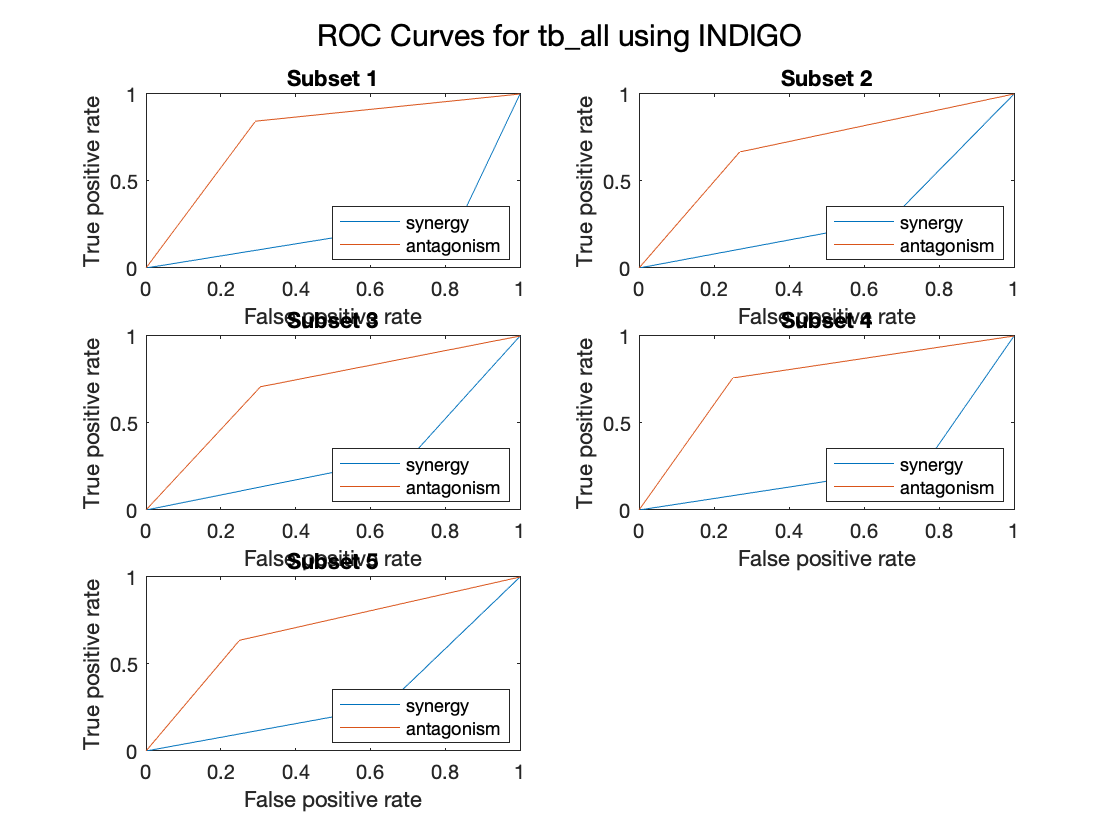

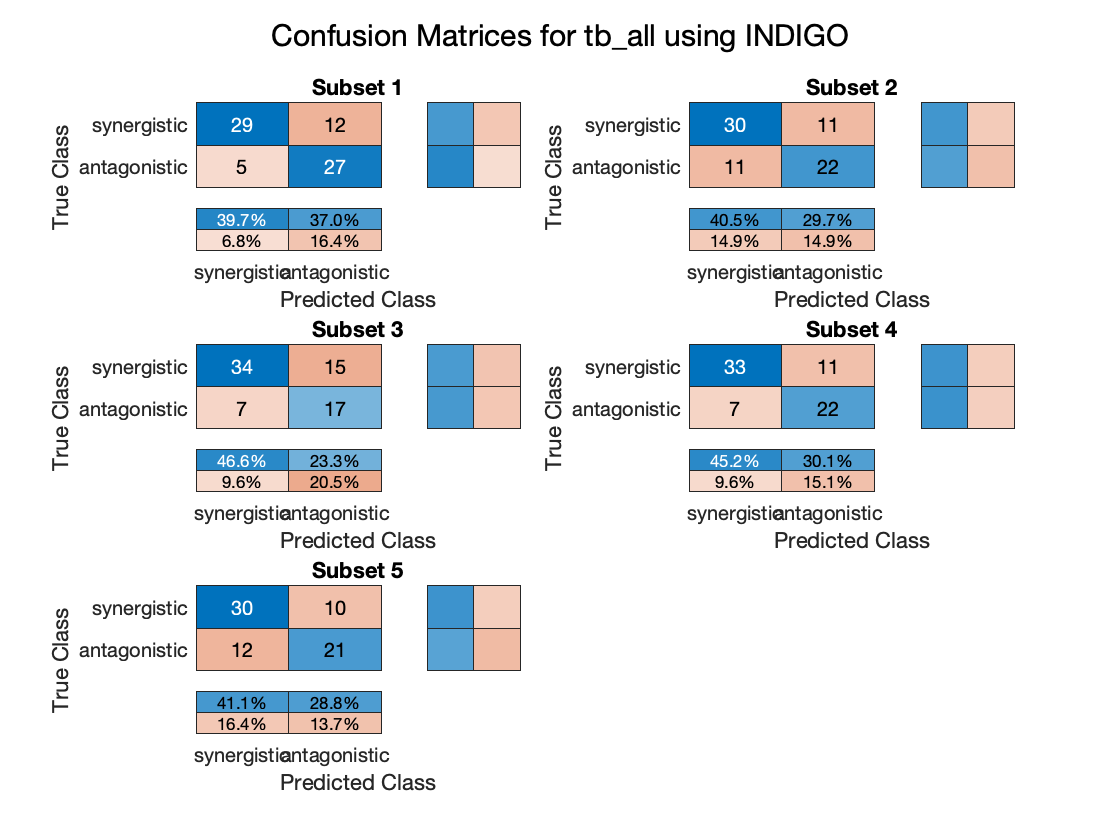

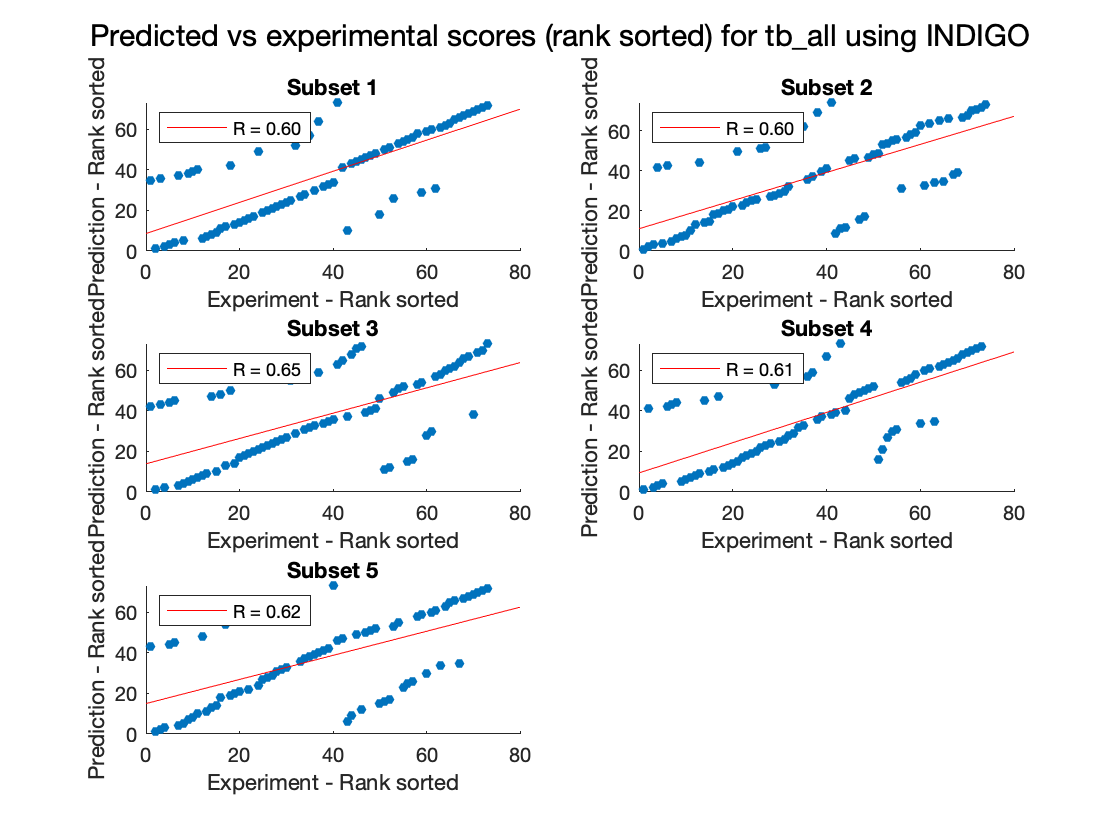

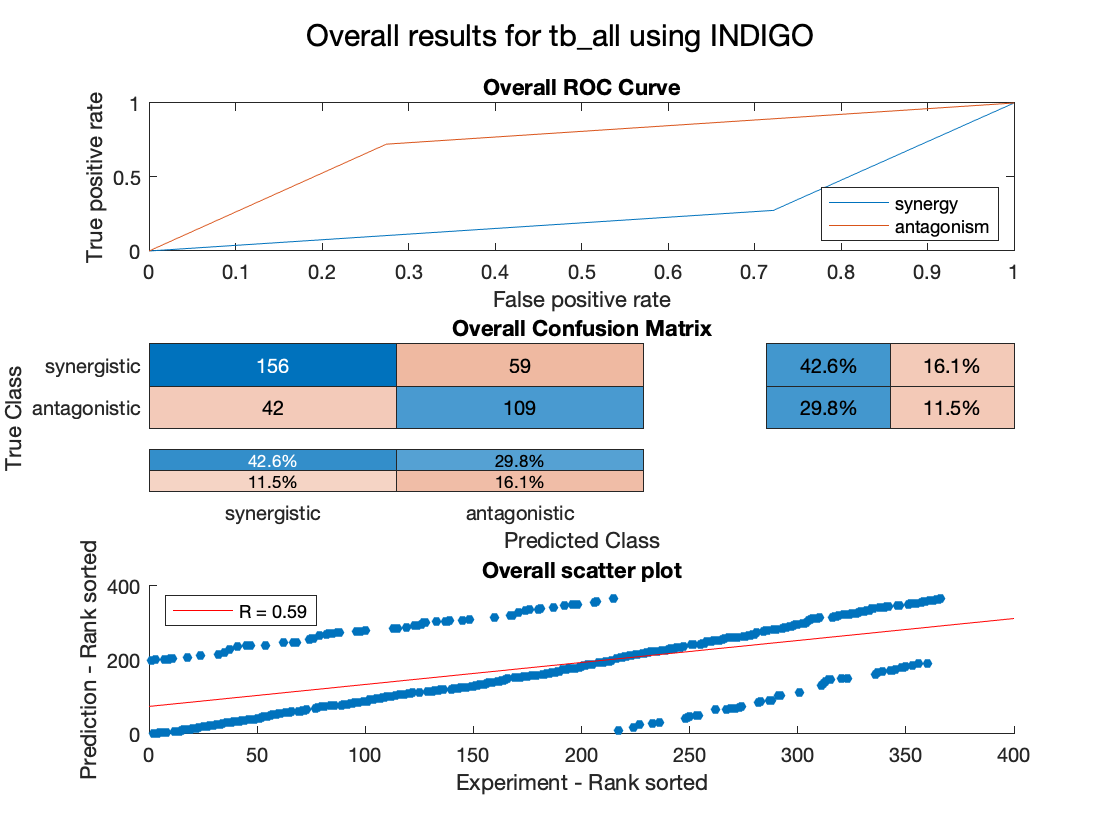

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         73         0.59791 

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                      73.2
    R (rank)                        0.6138
    P value                     1.1605e-08
    Accuracy                        0.7241
    Absolute error                  0.5518
    Precision (synergy)            0.79064
    Recall (synergy)               0.72658
    Precision (antagonism)         0.64686
    Recall (antagonism)            0.72275
    Guess Accuracy (p value)    2.1046e-55
    AUC - ROC (synergy)            0.27534
    AUC - ROC (antagonism)         0.72466


overviewTable = 12×1 table
                                   Value   
                                ___________

    Interactions                        366
    R (rank)                        0.58939
    P value                      1.3064e-35
    Accuracy                        0.72404
    Absolute error                  0.55191
    Precision (synergy)             0.78788
    Recall (synergy)                0.72558
    Precision (antagonism)          0.64881
    Recall (antagonism)             0.72185
    Guess Accuracy (p value)    2.4246e-101
    AUC - ROC (synergy)             0.27628
    AUC - ROC (antagonism)          0.72372


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_all.xlsx';
valMethod = 'cv_onself';
K = 5;
standardize = 'standardized';

indigoSummary = indigoRun_tb(testFile,normData,row,col,[],valMethod,K,standardize);

Run 1


Elapsed time is 14.182119 seconds.
Run 2
Elapsed time is 13.713307 seconds.
Run 3
Elapsed time is 14.057042 seconds.
Run 4
Elapsed time is 13.822648 seconds.
Run 5
Elapsed time is 13.941854 seconds.


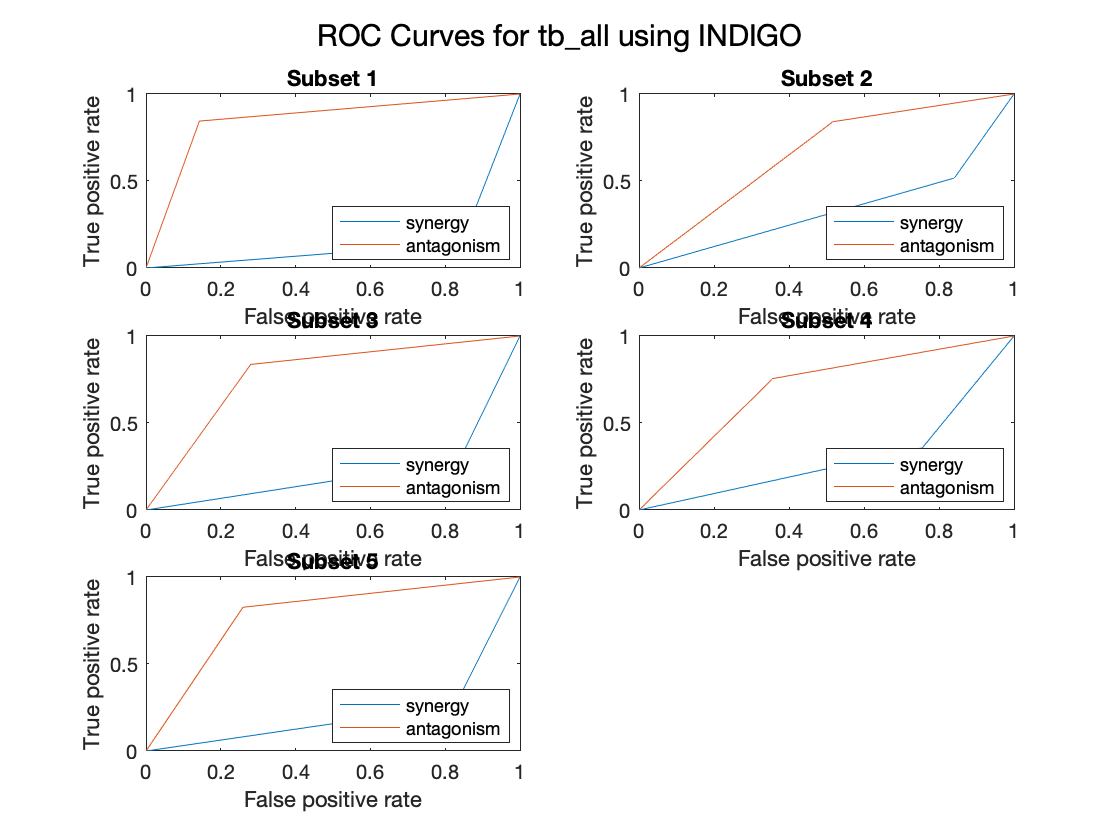

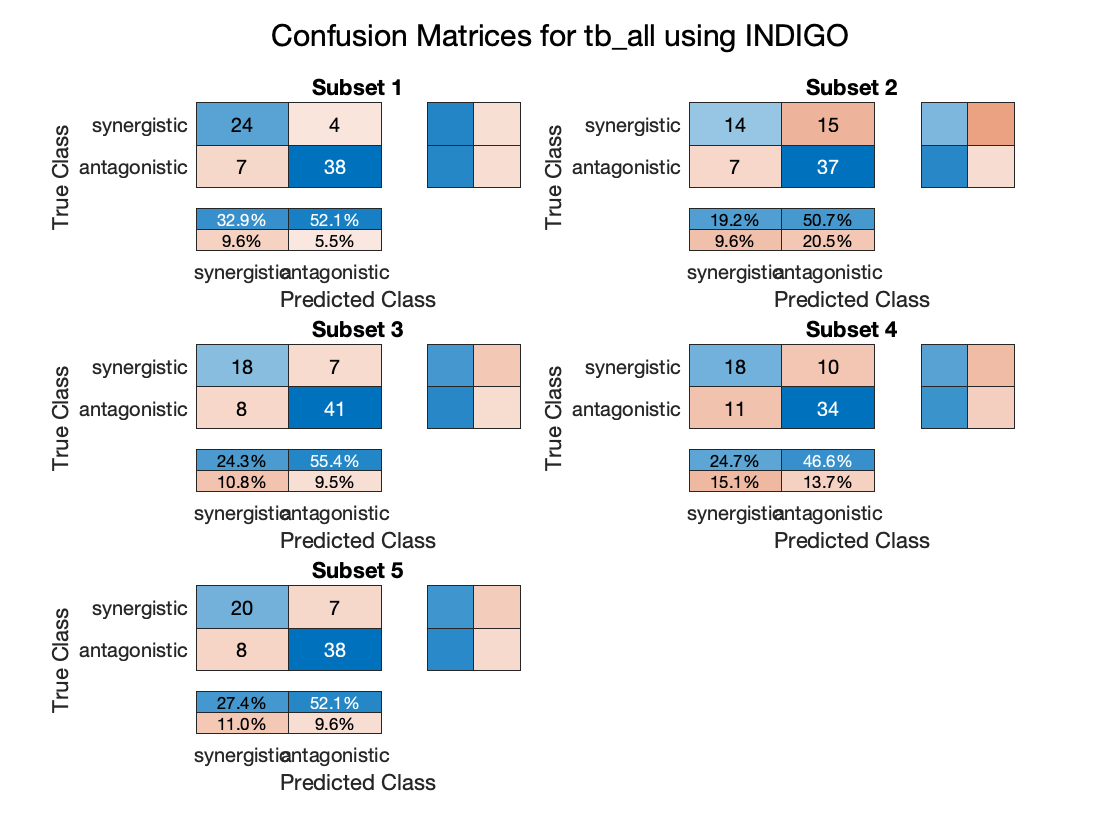

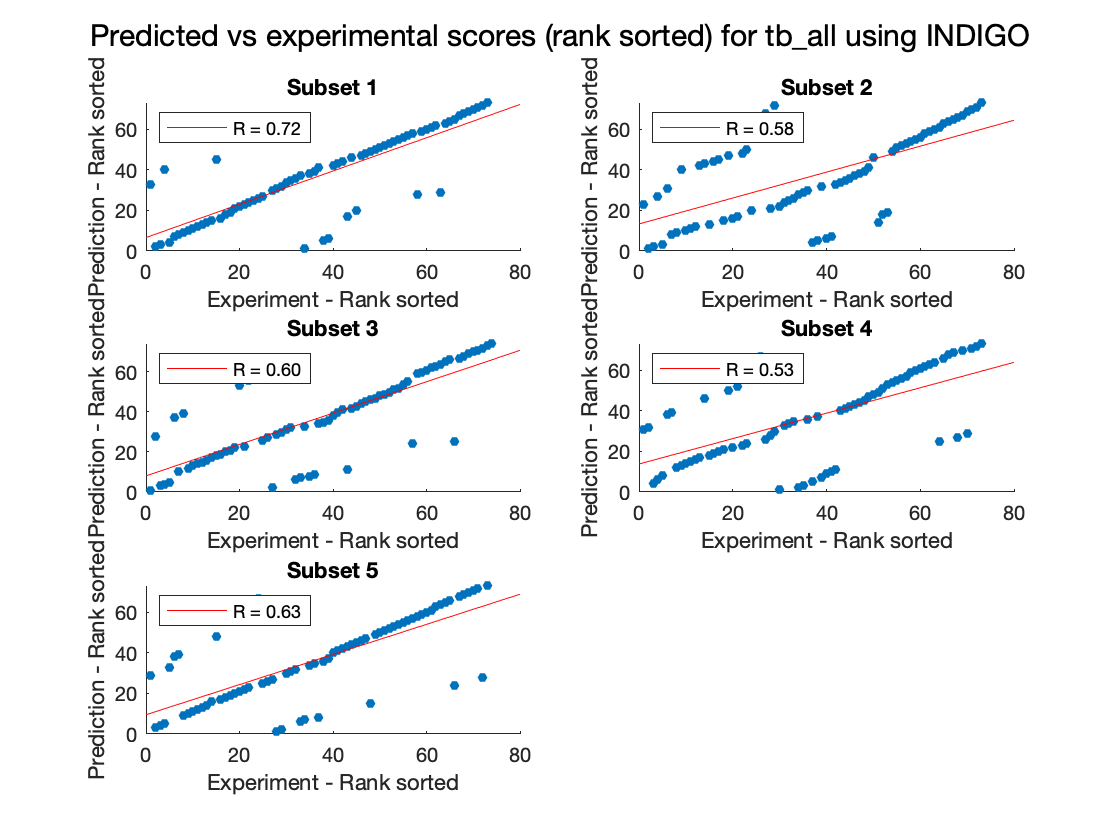

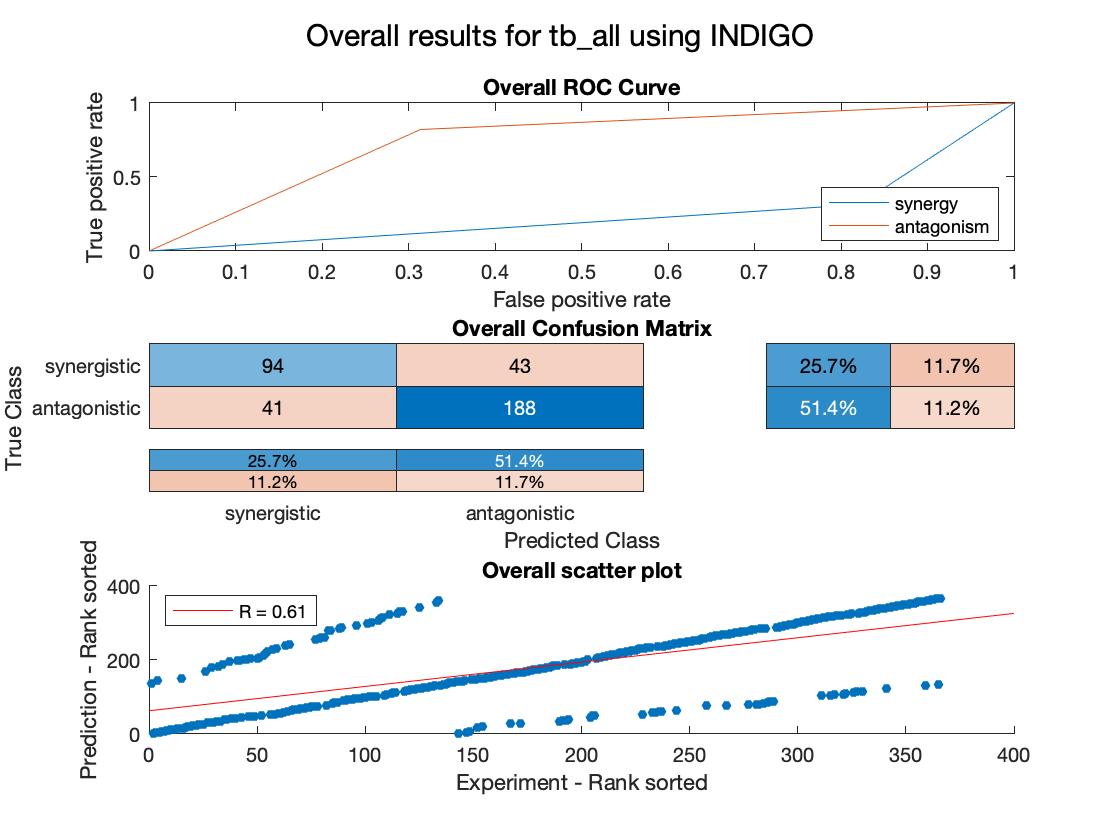

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         73         0.72149 

averagesTable = 12×1 table
                                  Value  
                                _________

    Interactions                     73.2
    R (rank)                      0.61241
    P value                     2.833e-07
    Accuracy                      0.77042
    Absolute error                0.45916
    Precision (synergy)           0.69363
    Recall (synergy)               0.6887
    Precision (antagonism)        0.81753
    Recall (antagonism)           0.82075
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.24528
    AUC - ROC (antagonism)        0.75472


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                       366
    R (rank)                       0.60976
    P value                     1.2202e-38
    Accuracy                       0.77049
    Absolute error                 0.45902
    Precision (synergy)             0.6963
    Recall (synergy)               0.68613
    Precision (antagonism)         0.81385
    Recall (antagonism)            0.82096
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.24645
    AUC - ROC (antagonism)         0.75355


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))